clear; clc; close all;
% Specifying the filenames of the audio files
transmitter_Audios = ["Short_BBCArabic2.wav", "Short_FM9090.wav", "Short_QuranPalestine.wav", "Short_RussianVoice.wav", "Short_SkyNewsArabia.wav"]; % names of audio files
% Obtaining maximum length

% Initialize variables used to store sums values or variables that may not store any values in the code.
max_audio_length = 0;
band_widths = cell(1, length(transmitter_Audios));  % Preallocate a cell array to hold the signals' bandwidth values.
BW_Of_chosen_Signal = 0;
BW_Of_last_Signal = 0;
current_sum = 0;
max_sum = 0;
FDM_Signal = 0; % Frequency Division Multiplexing
RF_Filter = 0;
%--------------------------------------
IF = 25000; % % If frequency 25 KHz

% Loop through each audio
for i = 1:length(transmitter_Audios) % i = 1:5
    % Read the audio file and obtain the audio data
    audio_signal = audioread(transmitter_Audios{i});
    
    % Calculate the length of the audio file (total number of samples)
    audio_length = size(audio_signal, 1); % '1' refers to one channel( one column )
    
    % Check if this audio file has the maximum length so far
    if audio_length > max_audio_length
        max_audio_length = audio_length;
    end
end

% Padding and Monoizing Audios
for i = 1:length(transmitter_Audios)
    % Read the audio file and obtain the audio data
    [audio_signal, Fs] = audioread(transmitter_Audios{i}); % getting audio data and sampling frequency
    audio_signal = sum(audio_signal, 2) / size(audio_signal, 2); % [2]Convert from stereo to mono ( The sum function adds the two channels & The size function determines the number of channels)

    % Padding short signals 
    audio_signal(end + max_audio_length - length(audio_signal)) = 0; % [3]short channels will be padded with zeros at the last remaining samples of its length after subtracting from maximum length
    
    audiowrite(transmitter_Audios{i}, audio_signal, Fs); % save the padded monoized audio signals 
end

% FFT Of Desired Audio At The Beginning
fprintf("Choose one of these channels:\n1. Short_BBCArabic2\n2. Short_FM9090\n3. Short_QuranPalestine\n4. Short_RussianVoice\n5. Short_SkyNewsArabia\n");

Choose one of these channels:
1. Short_BBCArabic2
2. Short_FM9090
3. Short_QuranPalestine
4. Short_RussianVoice
5. Short_SkyNewsArabia


sampling frequency for all audios = 44100 Hz


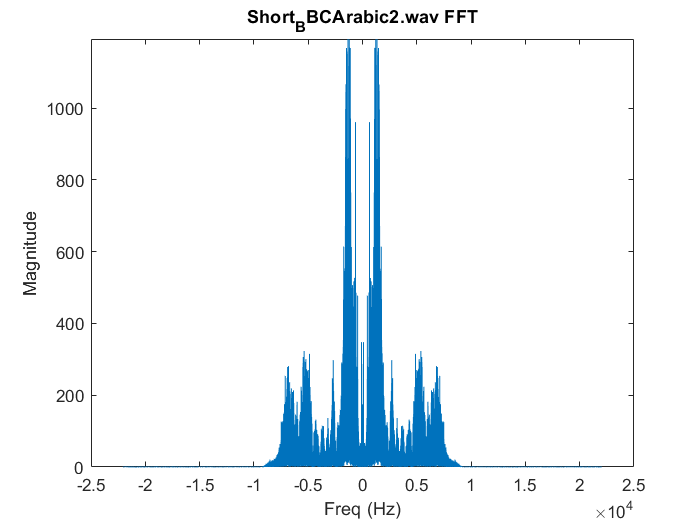

bandwidth of Short_BBCArabic2.wav = 9212.3327 Hz
bandwidth of Short_FM9090.wav = 22049.5831 Hz
bandwidth of Short_QuranPalestine.wav = 22049.7022 Hz
bandwidth of Short_RussianVoice.wav = 22049.6427 Hz
bandwidth of Short_SkyNewsArabia.wav = 9109.2502 Hz



choose_channel = input("Choose channel: "); 

for i = 1:length(transmitter_Audios)
    [audio_signal, Fs] = audioread(transmitter_Audios(i)); % Read audio and get sampling frequency
    
    if i == 1
        disp("sampling frequency for all audios = " + Fs + " Hz"); % [1] display sampling freq
    end
    %Fs = 44.1 khz
    AUDIO_SIGNAL = fftshift(fft(audio_signal, length(audio_signal))); % to be symmetric around 0 (this way give mathmatical meaning)
    Frequency_vector = (-length(AUDIO_SIGNAL)/2 : length(AUDIO_SIGNAL)/2 - 1)'; % adjust frequency axis (we converted it from row to column by (') because we next will divide it by the AUDIO_SIGNAL array which is a column array and dividing amd multiplying must be in same type)
    
    F = Frequency_vector*Fs/length(AUDIO_SIGNAL); % [4]Freq axis
    % freq limits [-Fs/2 ---> Fs/2]  exceeding this range will lead higher frequencies to fold back 

    if i == choose_channel
        plot(F, abs(AUDIO_SIGNAL)) % [5] plotting FFT
        title(transmitter_Audios(choose_channel) + " FFT")
        xlabel("Freq (Hz)")
        ylabel("Magnitude")
        ylim([0 max(abs(AUDIO_SIGNAL))])
    end
    
    % Obtaining BandWidth
    N = length(AUDIO_SIGNAL);
    [pks, freqs] = findpeaks(abs(AUDIO_SIGNAL(1:N/2)), F(1:N/2), 'MinPeakHeight', 0.001*max(abs(AUDIO_SIGNAL(1:N/2)))); % save frequencies and corresponding peaks which achieve the threshold(0.001*max) in two different arrays

    % Compute bandwidth
    bandwidth = max(freqs) - min(freqs);
    disp("bandwidth of " + transmitter_Audios(i) + " = " + bandwidth + " Hz");  %[6] BW
    
    band_widths{i} = bandwidth;

    if i == choose_channel
        BW_Of_chosen_Signal = bandwidth;
    end
    if i == length(transmitter_Audios)
        BW_Of_last_Signal = bandwidth;
    end
end

for i = choose_channel-1:choose_channel
    if choose_channel == 1
        max_sum = band_widths{choose_channel} + band_widths{choose_channel+1};
    elseif choose_channel == 5
        max_sum = band_widths{choose_channel} + band_widths{choose_channel-1};
    else
        current_sum = band_widths{i} + band_widths{i+1};
        if current_sum > max_sum
            max_sum = current_sum;
        end
    end
end
k0 = BW_Of_chosen_Signal + (50000 - max_sum); % the largest available frequency range for RF filter to use between two modulated consecutive signals
k_RF = k0 - 1000; %1000 as a safe factor.
disp("k_RF = " + num2str(k_RF) + " Hz");

k_RF = 26950.4169 Hz



k1 = IF; % the largest available frequency range for IF filter to use before exceeds 0
k_IF = k1 - 1000; %1000 as a safe factor.
disp("k_IF = " + num2str(k_IF) + " Hz");

k_IF = 24000 Hz



% Modulating
[audio_signal, Fs] = audioread(transmitter_Audios(choose_channel));
fo = 100000; 
n = (choose_channel-1);
delta_f = 50000;                                    
fn = fo + n*delta_f;

violation_1 = (2/Fs)*( fo + ( length(transmitter_Audios) - 1 ) * delta_f + BW_Of_last_Signal + k0 + 1000);             % violation of Nyquist criteria which appears after generarting FDM signal.
violation_2 = (2/Fs)*( fo + ( length(transmitter_Audios) - 1 ) * delta_f + 25000 + BW_Of_chosen_Signal + k1 +1000);    % violation of Nyquist criteria which appears after second modulation from Mixer.
                                                                                                                       % 1000 is another safe factor.
if violation_1 > violation_2
    x = violation_1;
else
    x = violation_2;
end
x = ceil(x);  % Round x up to the nearest greater integer
disp("violation_1 = " + num2str(violation_1));

violation_1 = 15.3315


disp("violation_2 = " + num2str(violation_2));

violation_2 = 16.3362


disp("x = " + num2str(x));

x = 17


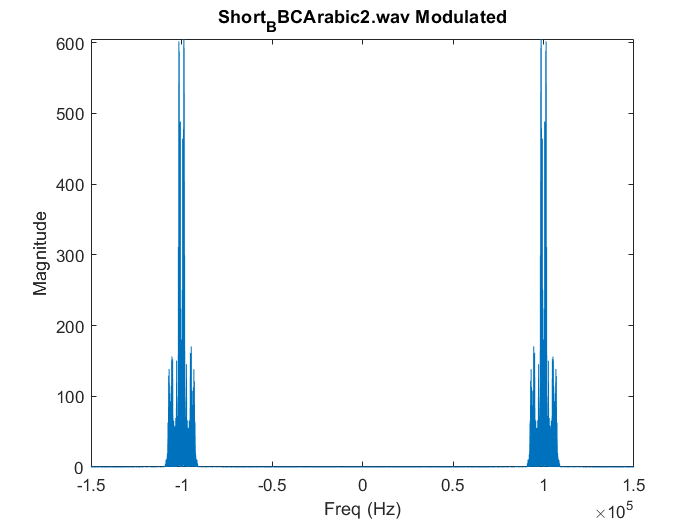


audio_signal = (1/x)*interp(audio_signal, x); %[8] Fs(new)= x*Fs & length(new) = x*length & magnitude(new) = x*magnitude so we divided by x to not change magnitude
audio_length = (1:1:length(audio_signal))'; % adjusted to be the same length as our signal
carrier_signal = cos(2*pi*fn*audio_length*(1/(x*Fs))); % [7] carrier signal cos(𝜔𝑛𝑛𝑇𝑆)

modulated_signal = carrier_signal.*audio_signal; % we use (.*) when multiplying arrays
MODULATED_SIGNAL = fftshift(fft(modulated_signal));
Frequency_vector = (-length(MODULATED_SIGNAL)/2:1:length(MODULATED_SIGNAL)/2-1)';

plot(Frequency_vector*(x*Fs)/length(MODULATED_SIGNAL), abs(MODULATED_SIGNAL))    
title(transmitter_Audios(choose_channel) + " Modulated")
xlabel("Freq (Hz)")
ylabel("Magnitude")
xlim([-1.5*fn 1.5*fn])
ylim([0 max(abs(MODULATED_SIGNAL))])

    
bandwidth2 = 2 * BW_Of_chosen_Signal;
disp("bandwidth of " + transmitter_Audios(choose_channel) + " Modulated = " + bandwidth2 + " Hz");

bandwidth of Short_BBCArabic2.wav Modulated = 18424.6654 Hz


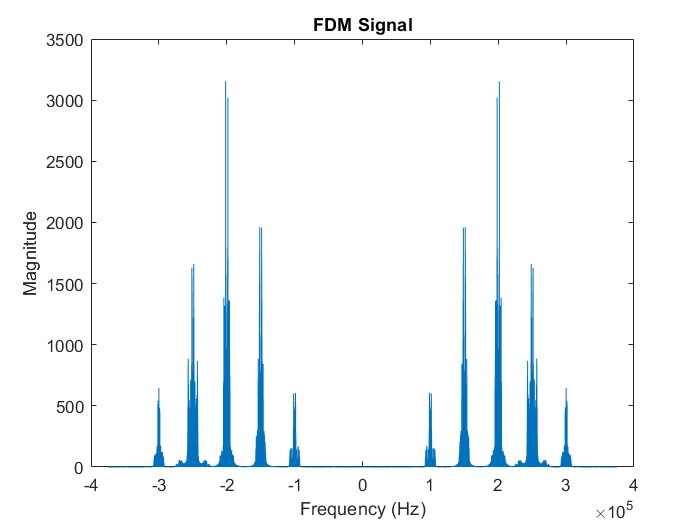


% FDM Signal Generation
for i = 1:length(transmitter_Audios)
    % Read the audio file and obtain the audio data
    [audio_signal, Fs] = audioread(transmitter_Audios(i)); % Read audio and get sampling frequency
    audio_signal = (1/x)*interp(audio_signal, x); %
    
    fo = 100000;
    n = (i-1);
    delta_f = 50000;
    fn = fo + n*delta_f;
                 
    audio_length = (1:1:length(audio_signal))';
    carrier_signal = cos(2*pi*fn*audio_length*(1/(x*Fs))); % [7] carrier signal
   
    modulated_signal = carrier_signal.*audio_signal;
    FDM_Signal = FDM_Signal + modulated_signal; % summing point 
end
FDM_SIGNAL = fftshift(fft(FDM_Signal));
Frequency_vector = (-length(FDM_SIGNAL)/2:length(FDM_SIGNAL)/2-1)';
plot(Frequency_vector*(x*Fs)/length(FDM_SIGNAL), abs(FDM_SIGNAL))
title("FDM Signal")
xlabel("Frequency (Hz)")
ylabel("Magnitude")


% The RF stage
fprintf("Choose:\n0. Normal operation\n1. Remove RF Filter\n2. 0.1kHz Offset\n3. 1kHz Offset\n");

Choose:
0. Normal operation
1. Remove RF Filter
2. 0.1kHz Offset
3. 1kHz Offset


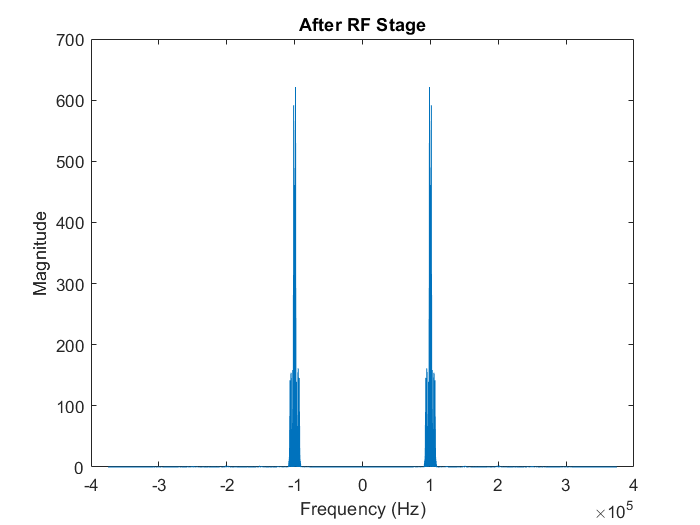


test = input("0. Normal operation\n1. Remove RF Filter\n2. 0.1kHz Offset\n3. 1kHz Offset\n Choose test : ");
if test ~= 1
    width = 1.8*k_RF; % width of the any filter should be bigger as much as possible than our signal Bandwidth to avoid phase distortion , note: ( fstop1 & fstop2 practically should be far away from fpass1,2 because this filter works at very high frequncy and cannot be precise but the frequncy carrrier given 100k >> 300k is very small to can give practical numbers prameters)
    A_stop1 = 60; % Attenuation in the first stopband = 60 dB
    F_stop1 = (choose_channel-1)*50000+100000-k_RF;          % Edge of the first  stopband = (fn-k_RF) [We choosed high k value that filter can use before interacting with another signal as it is not high selective filter and not practical to decrease k]
    F_pass1 = (choose_channel-1)*50000+100000-0.5*width;  % Edge of the first  passband = fn-0.5*width
    F_pass2 = (choose_channel-1)*50000+100000+0.5*width;  % Edge of the second passband = fn+0.5*width 
    F_stop2 = (choose_channel-1)*50000+100000+k_RF;          % Edge of the second stopband = (fn+k_RF) making it symmetric is better
    A_stop2 = 60;                                         % Attenuation in the second stopband = 60 dB
    A_pass = 1; % Amount of ripple allowed in the passband

    RF_Filter = fdesign.bandpass(F_stop1, F_pass1, F_pass2, F_stop2, A_stop1, A_pass, A_stop2, (x*Fs));
    RF_Filter = design(RF_Filter, 'equiripple'); % equiripple is good in dealing with ripples espicially in bandpass filter 

    RF_Signal  = filter(RF_Filter, FDM_Signal);
    RF_SIGNAL  = fftshift(fft(RF_Signal));
    Frequency_vector = (-length(RF_SIGNAL)/2:1:length(RF_SIGNAL)/2-1)';

    plot(Frequency_vector*(x*Fs)/length(RF_SIGNAL), abs(RF_SIGNAL))
    title("After RF Stage")
    xlabel("Frequency (Hz)")
    ylabel("Magnitude")
end

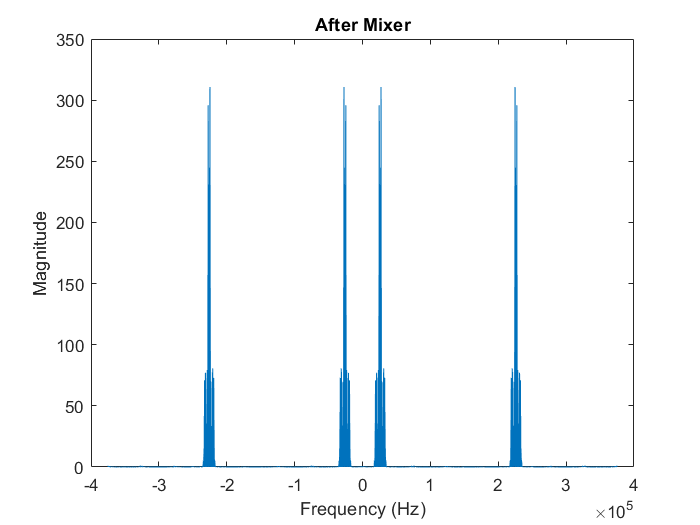


% Mixer (Oscillator 𝜔𝐶 + 𝜔𝐼f)
fn = (choose_channel-1)*50000+100000; % [100, 150, 200, 250, 300] KHz
fLo = fn + IF; % Local oscillator carrier frequency

if test == 1
    RF_Signal = FDM_Signal;  
elseif test == 2
    fLo = fLo + 100; % 0.1k offset
elseif test == 3
    fLo = fLo + 1000; % 1k offset
end       

audio_length = (1:1:length(RF_Signal))';
carrier_signal = cos(2*pi*fLo*audio_length*(1/(x*Fs)));

Mixer_Output_Signal = RF_Signal.*carrier_signal;
MIXER_OUTPUT_SIGNAL = fftshift(fft(Mixer_Output_Signal));
Frequency_vector = (-length(MIXER_OUTPUT_SIGNAL)/2:1:length(MIXER_OUTPUT_SIGNAL)/2-1)';

plot(Frequency_vector*(x*Fs)/length(MIXER_OUTPUT_SIGNAL), abs(MIXER_OUTPUT_SIGNAL))
title(" After Mixer ")
xlabel("Frequency (Hz)")
ylabel("Magnitude")

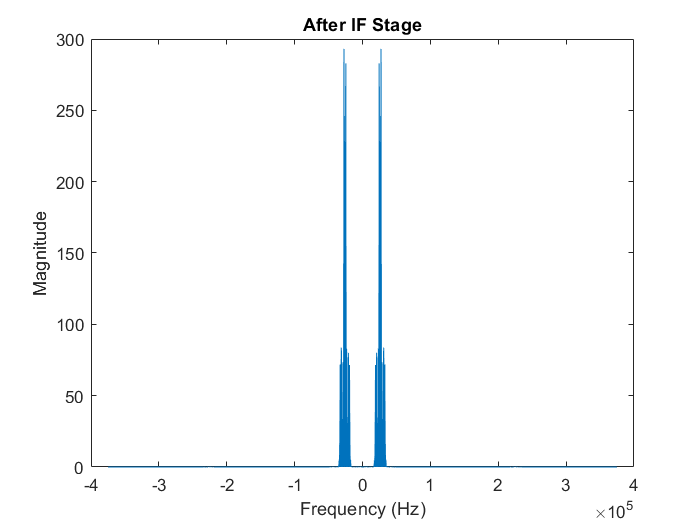


% IF stage
width = 1.8*k_IF;                         % 1.8 is just to give wider width and some freq range for stop bands(0.1k for both stop band). 
A_stop1 = 60;                             % Attenuation in the first stopband = 60 dB
F_stop1 = IF-k_IF;                        % Edge of the first  stopband (2000 is used as this filter is high selective and decreasing it makes operation  much slower due to higher filter order will be implemented )
F_pass1 = IF-0.5*width;                   % Edge of the first  passband
F_pass2 = IF+0.5*width;                   % Edge of the second passband
F_stop2 = IF+k_IF;                        % Edge of the second stopband
A_stop2 = 60;                             % Attenuation in the second stopband = 60 dB
A_pass = 1;                               % Amount of ripple allowed in the passband = 1 dB

IF_Filter = fdesign.bandpass(F_stop1, F_pass1, F_pass2, F_stop2, A_stop1, A_pass, A_stop2, (x*Fs));
IF_Filter = design(IF_Filter, 'equiripple');
IF_Signal  = filter(IF_Filter, Mixer_Output_Signal);
%IF_Signal = 1.5*IF_Signal; % amplification

IF_SIGNAL  = fftshift(fft(IF_Signal));
Frequency_vector = (-length(IF_SIGNAL)/2:1:length(IF_SIGNAL)/2-1)';

plot(Frequency_vector*(x*Fs)/length(IF_SIGNAL), abs(IF_SIGNAL))
title("After IF Stage")
xlabel("Frequency (Hz)")
ylabel("Magnitude")

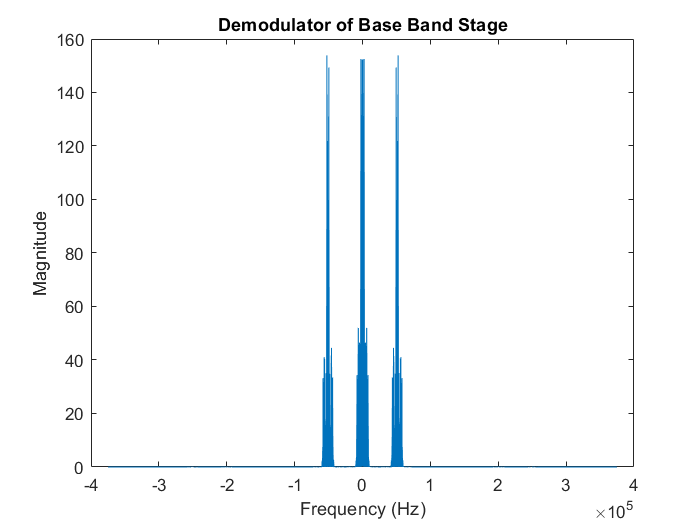


% Base Band Stage (Demodulation)
fc = IF; % BaseBand carrier frequency

audio_length = (1:1:length(IF_Signal))';
carrier_signal = cos(2*pi*fc*audio_length*(1/(x*Fs)));

Base_Band_Signal = IF_Signal.*carrier_signal;
BASE_BAND_SIGNAL = fftshift(fft(Base_Band_Signal));
Frequency_vector = (-length(BASE_BAND_SIGNAL)/2:1:length(BASE_BAND_SIGNAL)/2-1)';

plot(Frequency_vector*(x*Fs)/length(BASE_BAND_SIGNAL), abs(BASE_BAND_SIGNAL))
title("Demodulator of Base Band Stage")
xlabel("Frequency (Hz)")
ylabel("Magnitude")


% The Base Band detection (LPF)
k2 = 50000 - 2*BW_Of_chosen_Signal; % the largest available frequency range for BaseBand filter to use before interacting with its image.
k_BB = k2 - 1000; %1000 as a safe factor.
disp("k_BB = " + num2str(k_BB) + " Hz");

k_BB = 30575.3346 Hz


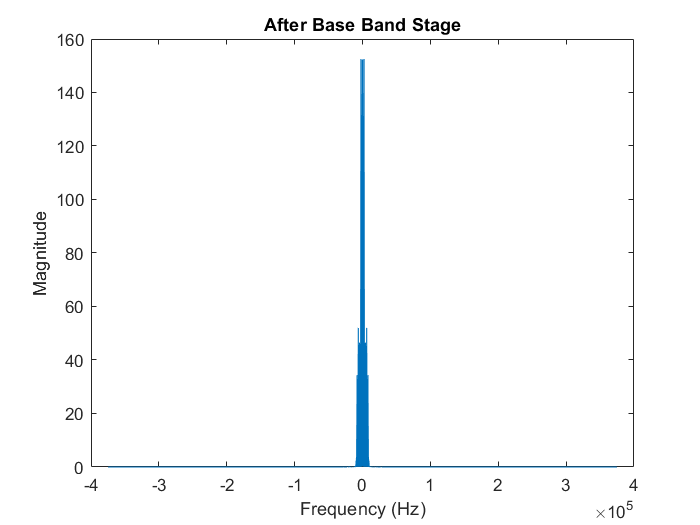


width = 0.9*k_BB;
F_stop = k_BB;                            % Edge of the stopband ( we have good available range of frequencies to increase F_stop so F_stop = 2 * F_pass is good enough)
F_pass = width;                           % Edge of the passband (original bandwidth of the signal)
A_stop = 60;                              % Attenuation in stopband
A_pass = 1;                               % Amount of ripple allowed in the passband

Base_Band_Filter = fdesign.lowpass(F_pass, F_stop, A_pass, A_stop, (x*Fs));
Base_Band_Filter = design(Base_Band_Filter, 'butter'); % Using a lower-order Butterworth filter could provide a good balance between frequency selectivity and phase linearity.
Base_Band_Signal  = filter(Base_Band_Filter, Base_Band_Signal);
BASE_BAND_SIGNAL  = fftshift(fft(Base_Band_Signal));
Frequency_vector = (-length(BASE_BAND_SIGNAL)/2:1:length(BASE_BAND_SIGNAL)/2-1)';

plot(Frequency_vector*(x*Fs)/length(BASE_BAND_SIGNAL), abs(BASE_BAND_SIGNAL))
title("After Base Band Stage")
xlabel("Frequency (Hz)")
ylabel("Magnitude")

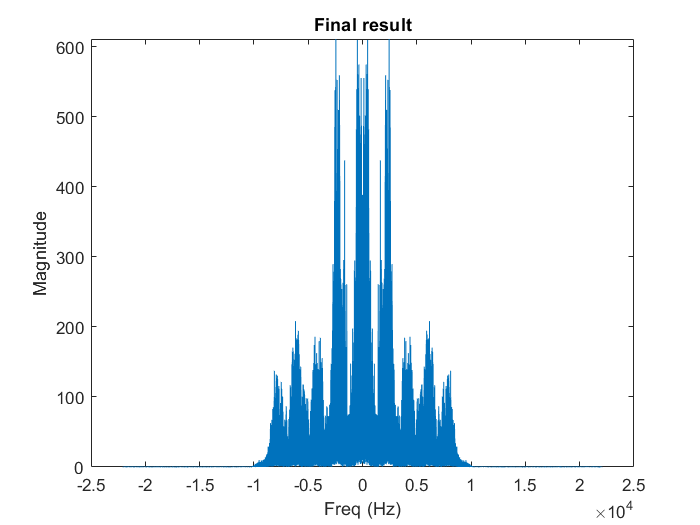


Base_Band_Signal = 4*x*resample(Base_Band_Signal, 1, x); % restore main Fs & length by doing the opposite the interp do & multiplied by x because it divides magnitude by x and multiplied by another 4 due to two modulation processses

BASE_BAND_SIGNAL  = fftshift(fft(Base_Band_Signal));
Frequency_vector = (-length(BASE_BAND_SIGNAL)/2:1:length(BASE_BAND_SIGNAL)/2-1)';

figure
plot((Frequency_vector*Fs/length(BASE_BAND_SIGNAL)), abs(BASE_BAND_SIGNAL))
title("Final result")
xlabel("Freq (Hz)")
ylabel("Magnitude")
ylim([0 max(abs(BASE_BAND_SIGNAL))])


sound(Base_Band_Signal, Fs) % to listen to our station

% --------------------saving received signals & different tests-----------------------------
% Normalize the Base_Band_Signal before saving
disp(max(abs(Base_Band_Signal)));

    1.1039



Base_Band_Signal = Base_Band_Signal / max(abs(Base_Band_Signal));  % Normalize to range [-1, 1] because it could potentially has been changed during the code
errors = ["Removed_RF for " + transmitter_Audios(choose_channel), "0.1 KHz Offset for " + transmitter_Audios(choose_channel), "1 KHz Offset for "+ transmitter_Audios(choose_channel)]; % three tests
receiver = ["received_BBCArabic2.wav", "received_FM9090.wav", "received_QuranPalestine.wav", "received_RussianVoice.wav", "received_SkyNewsArabia.wav"];

if test == 1 || test == 2 || test == 3
    audiowrite(errors{test}, Base_Band_Signal, Fs); % save test audios, Test{1} Test{2} Test{3}
else
    audiowrite(receiver{choose_channel}, Base_Band_Signal, Fs);
end
